# Script de Bode

clear
clc

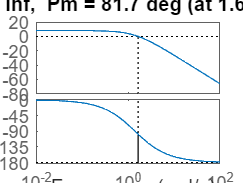


s = tf('s');

Kp = 5;

C = Kp;
P = 1/((s+1)*(s+2));

L = C*P;
margin(L)


sens = 1/(L+1)

sens =
 
  s^2 + 3 s + 2
  -------------
  s^2 + 3 s + 7
 
Continuous-time transfer function.
Model Properties


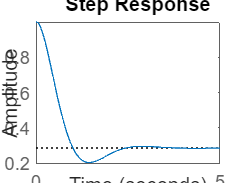


step(sens)

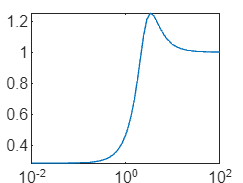

[mag, phase, w] = bode(sens);
magnitude_abs = squeeze(mag);
semilogx(w, magnitude_abs);

Ms = max(magnitude_abs)

Ms = 1.2502

s = tf('s');
a=1.81;
ex = a/(s^2 +a*s + a)
step(ex)